Detector = load("DetectorARMChallenge2.mat").Detector1;
colorImage = imread("C:\Users\RoboIME\Desktop\fotos\306calib.png");
depthImage = imread("C:\Users\RoboIME\Desktop\fotos\306_d.png");

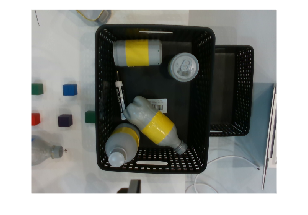

        imshow(colorImage);

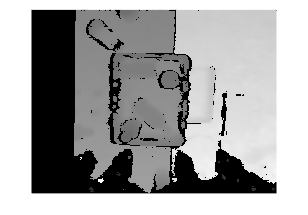

        imshow(depthImage);

        
        pack = cell(1,3);
        pack{1} = Detector;
        pack{2} = colorImage;
        pack{3} = depthImage;
        
        [~,~,objSem,~,~] = PcGenRSD435(pack)

objSem = 1×9 cell array
    {1×1 pointCloud}    {1×1 pointCloud}    {1×1 pointCloud}    {1×1 pointCloud}    {1×1 pointCloud}    {1×1 pointCloud}    {1×1 pointCloud}    {1×1 pointCloud}    {1×1 pointCloud}


Pontos iniciais: 307200 | Após filtro: 254169
Pontos iniciais: 930 | Após filtro: 42
Pontos iniciais: 1216 | Após filtro: 1033
Pontos iniciais: 928 | Após filtro: 725
Pontos iniciais: 1184 | Após filtro: 906
Pontos iniciais: 10087 | Após filtro: 8509
Pontos iniciais: 6642 | Após filtro: 3963
Pontos iniciais: 27360 | Após filtro: 21657
Pontos iniciais: 10353 | Após filtro: 6937
Pontos iniciais: 10087 | Após filtro: 8509
Pontos iniciais: 6642 | Após filtro: 3963
Pontos iniciais: 27360 | Após filtro: 21657
Pontos iniciais: 10353 | Após filtro: 6937


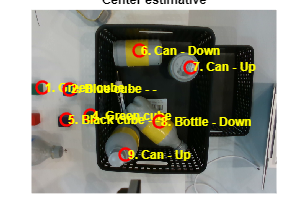

displacement = 2×9 single matrix
   -0.2942   -0.2294         0   -0.1774   -0.2421   -0.0366    0.0797    0.0119   -0.0584
    0.0319    0.0280         0   -0.0441   -0.0557    0.1179    0.0719   -0.0550   -0.1127


idx =      1     3


sts = 9×1 categorical array
     - 
     - 
     - 
     - 
     - 
     Down 
     Up 
     Down 
     Up 


labels = 9×1 categorical array
     Green_cube 
     Blue_cube 
     Red_cube 
     Green_cube 
     Black_cube 
     Can 
     Can 
     Bottle 
     Can 


scores = 9×1 single column vector
    0.8478
    0.8541
    0.8302
    0.7953
    0.8722
    0.8553
    0.8963
    0.6361
    0.6222


          
        [displacement,idx,sts,labels,scores] = ARMVision(colorImage,depthImage,Detector,0.6)

        
       
        % === Calcular esdados e rot ===
        rots = {}


rots =

  0×0 empty cell array



        for i=1:size(sts)
        
            dzInicial = 0.05;
            minPontosInicial = 3000;
            ptobjeto = objSem{i};
        
            [~, ptselecao] = supPlane(ptobjeto, dzInicial, minPontosInicial);
            
            if sts(i) == "Up"
                rot = 0;
            elseif sts(i) == "Down"
                rot = Calcular_rot(ptselecao,UR5);
            end
            rots{end + 1} = rot;
        end

Ângulo theta dominante: -1.19 graus


Error using codertarget.urseries.internal.urTransportLayer.urTransportLayer/read (line 111)
Invalid operation. Object must be connected to the remote server.

Error in 